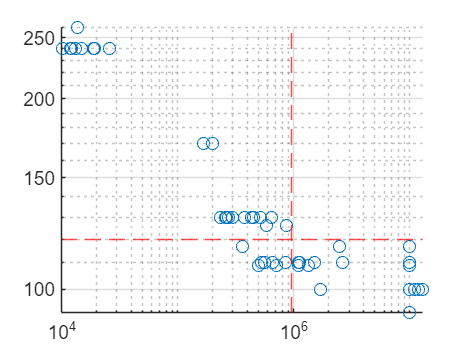

clear all
clf
format shortg

% data = xlsread("fatigue_data.xlsx")r;
load("fatigue_data.mat")
% data_size = size(data)

scatter(N,S)
yscale log
xscale log
grid("on")

N_D = 9.5*1e5;
S_D = 120;
yline(S_D, 'r--')
xline(N_D, 'r--')


data = [N, S, RO];

data2 = [];

for i = 1:length(N)
    if N(i) < N_D && RO(i)==0
        data2(end+1,1:2) = data(i,1:2);
    end
end

N2 = data2(:,1)

N2 =       518000
      265000
      448000
      647000
      431000
      232000
      277000
      298000
      378000
      261000


S2 = data2(:,2)

S2 =    130
   130
   130
   130
   130
   130
   130
   130
   130
   130


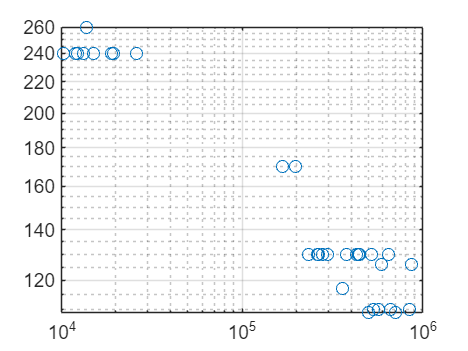


loglog(N2, S2,"o")
grid("on")


N2_log = log10(N2);
S2_log = log10(S2);

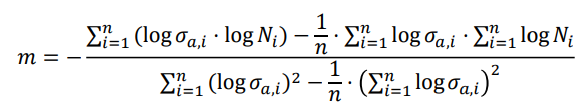

m = m_fun(S2,N2) % made as a matlab fuction in m_fun.m

m =         4.863


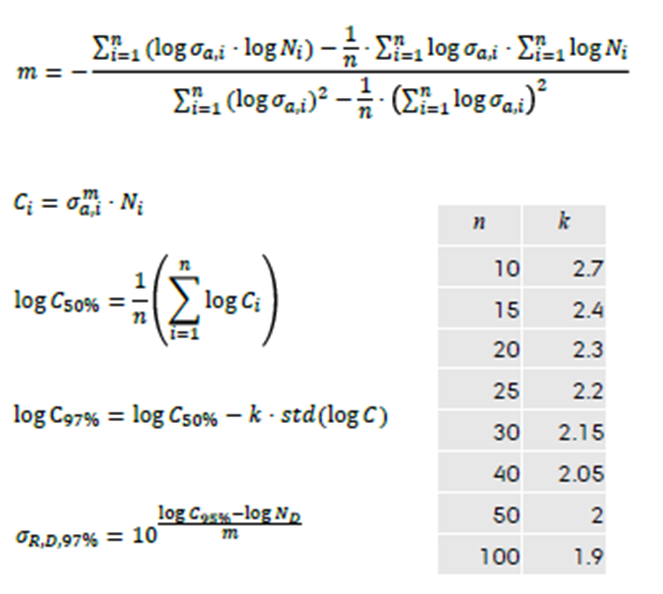

% sigma_RD_50 = (log(C_50) - log(N_D))/m

C_50 = N2 .* S2.^m

C_50 =    9.8705e+15
   5.0496e+15
   8.5366e+15
   1.2329e+16
   8.2127e+15
   4.4208e+15
   5.2782e+15
   5.6784e+15
   7.2028e+15
   4.9734e+15


C_50_log10 = sum(log(C_50))

C_50_log10 =        1129.3



sigma_RD_50_log = (C_50_log10 - log(N_D))/m

sigma_RD_50_log =        229.39


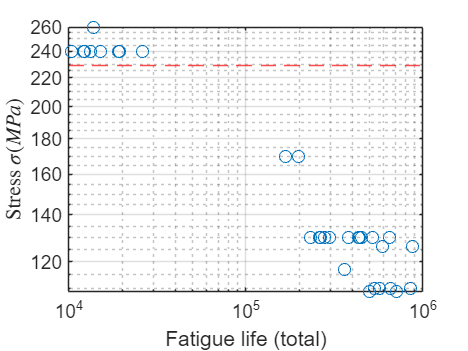

% syms sigma_fun(x) x
% % sigma_fun(x) = -(log10(mean(S2)) - log10(x))/m;

% Xs = linspace(10e4,10e6,200);


loglog(N2, S2,"o")
hold on
% loglog(Xs, sigma_fun(Xs))
yline(sigma_RD_50_log,"r--")
xlabel("Fatigue life (total)")
ylabel("Stress $\sigma (MPa)$", Interpreter="latex")
grid("on")